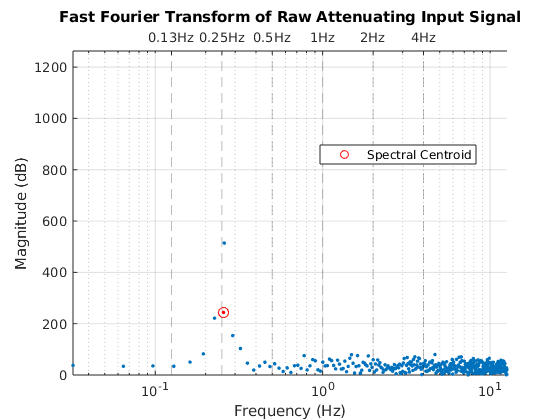

clc, clear all, close all;

path = pwd + "/15bpm3c40sps_2-00sw/";
r_fullpath = join([path, "02_rawfft.csv"], "");
r_num = readmatrix(r_fullpath);
t_fullpath = join([path, "02_transformedfft.csv"], "");
t_num = readmatrix(t_fullpath);

r_frq = r_num(1:end - 1, 2);
r_mag = r_num(1:end - 1, 3);
r_sc = [r_num(end, 2) r_num(end, 3)];
r_max_y = max(r_mag) + 100;

t_frq = t_num(1:end - 1, 2);
t_mag = t_num(1:end - 1, 3);
t_sc = [t_num(end, 2) t_num(end, 3)];
t_max_y = max(t_mag) + 100;

max_y = max([t_max_y, r_max_y]);
min_x = min([min(r_frq) min(t_frq)]);
max_x = max([max(r_frq) max(t_frq)]);

figure; hold on;
r1 = scatter(r_frq, r_mag, 60, '.');
r2 = scatter(r_sc(1), r_sc(2), 60, 'red', '.');
r3 = scatter(r_sc(1), r_sc(2), 60, 'red', 'o');

xline(0.125, '--', 'Alpha', 0.3);
xline(0.25, '--', 'Alpha', 0.3);
xline(0.5, '--', 'Alpha', 0.3);
xline(1, '--', 'Alpha', 0.3);
xline(2, '--', 'Alpha', 0.3);
xline(4, '--', 'Alpha', 0.3);
hold off;

ax1 = gca;
set(ax1, 'xscale', 'log');
set(ax1, 'OuterPosition', [0 0 1 0.95]);

xlabel('Frequency (Hz)'), ylabel('Magnitude (dB)');
grid on, t = title('Fast Fourier Transform of Raw Attenuating Input Signal', 'Units', 'normalized');
set(t, 'Position', get(t, 'Position') + [0, 0.07, 0]);

legend([r3], 'Spectral Centroid', 'location', 'best');
ylim([0, max_y]);
xlim([min_x, max_x]);

ax2 = axes('Position', ax1.Position, ...
    'XAxisLocation', 'top', ...
    'YColor', 'none', 'Color', 'none');
set(ax2, 'xscale', 'log');
linkaxes([ax1, ax2], 'x');
xticks(ax2, [0.125 0.25 0.5 1 2 4]);
xticklabels({'0.13Hz', '0.25Hz', ...
    '0.5Hz', '1Hz', '2Hz', '4Hz'})

figure; hold on;
t1 = scatter(t_frq, t_mag, 60, '.');
t2 = scatter(t_sc(1), t_sc(2), 60, 'red', '.');
t3 = scatter(t_sc(1), t_sc(2), 60, 'red', 'o');

xline(0.125, '--', 'Alpha', 0.3);
xline(0.25, '--', 'Alpha', 0.3);
xline(0.5, '--', 'Alpha', 0.3);
xline(1, '--', 'Alpha', 0.3);
xline(2, '--', 'Alpha', 0.3);
xline(4, '--', 'Alpha', 0.3);
hold off;

ax1 = gca;
set(ax1, 'xscale', 'log');
set(ax1, 'OuterPosition', [0 0 1 0.95]);

xlabel('Frequency (Hz)'), ylabel('Magnitude (dB)');
grid on, t = title('Fast Fourier Transform of Raw Attenuating Input Signal', 'Units', 'normalized');
set(t, 'Position', get(t, 'Position') + [0, 0.07, 0]);

legend([t3], 'Spectral Centroid', 'location', 'best');
ylim([0, max_y]);
xlim([min_x, max_x]);

ax2 = axes('Position', ax1.Position, ...
    'XAxisLocation', 'top', ...
    'YColor', 'none', 'Color', 'none');
set(ax2, 'xscale', 'log');
linkaxes([ax1, ax2], 'x');

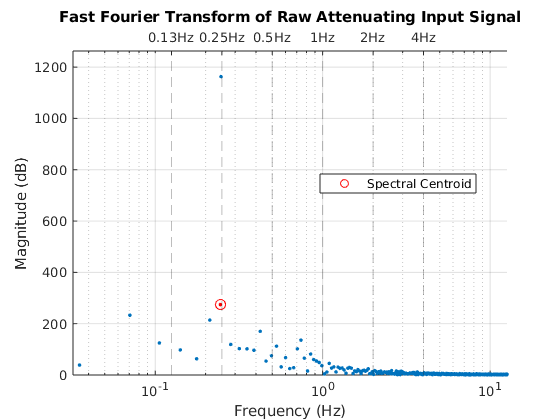

xticks(ax2, [0.125 0.25 0.5 1 2 4]);
xticklabels({'0.13Hz', '0.25Hz', ...
    '0.5Hz', '1Hz', '2Hz', '4Hz'})

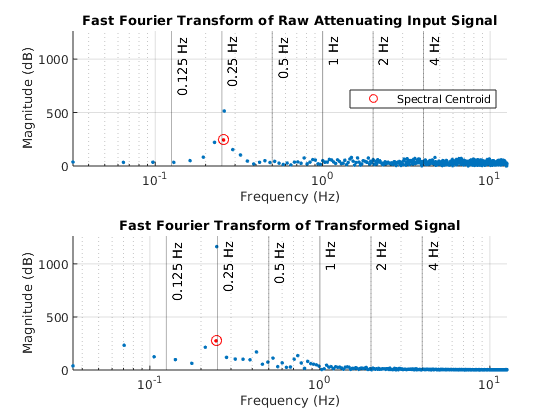


figure;
tiledlayout(2, 1);

ax1 = nexttile;
hold on;
r1 = scatter(r_frq, r_mag, 60, '.');
r2 = scatter(r_sc(1), r_sc(2), 60, 'red', '.');
r3 = scatter(r_sc(1), r_sc(2), 60, 'red', 'o');

xline(0.125, 'black', '0.125 Hz', 'Alpha', 0.3);
xline(0.25, 'black', '0.25 Hz', 'Alpha', 0.3);
xline(0.5, 'black', '0.5 Hz', 'Alpha', 0.3);
xline(1, 'black', '1 Hz', 'Alpha', 0.3);
xline(2, 'black', '2 Hz', 'Alpha', 0.3);
xline(4, 'black', '4 Hz', 'Alpha', 0.3);
set(gca,'xscale','log')
hold off;

xlabel('Frequency (Hz)'), ylabel('Magnitude (dB)');
grid on, title('Fast Fourier Transform of Raw Attenuating Input Signal');
legend([r3], 'Spectral Centroid', 'location', 'east');
ylim([0, max_y]);
xlim([0, max_x]);

ax2 = nexttile;
hold on;
t1 = scatter(t_frq, t_mag, 60, '.');
t2 = scatter(t_sc(1), t_sc(2), 60, 'red', '.');
t3 = scatter(t_sc(1), t_sc(2), 60, 'red', 'o');

xline(0.125, 'black', '0.125 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
xline(0.25, 'black', '0.25 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
xline(0.5, 'black', '0.5 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
xline(1, 'black', '1 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
xline(2, 'black', '2 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
xline(4, 'black', '4 Hz', 'Alpha', 0.3, 'LabelVerticalAlignment', 'top');
set(gca,'xscale','log')
hold off;

xlabel('Frequency (Hz)'), ylabel('Magnitude (dB)');
grid on, title('Fast Fourier Transform of Transformed Signal');
ylim([0, max_y]);
xlim([0, max_x]);